clear;
clc;

#### 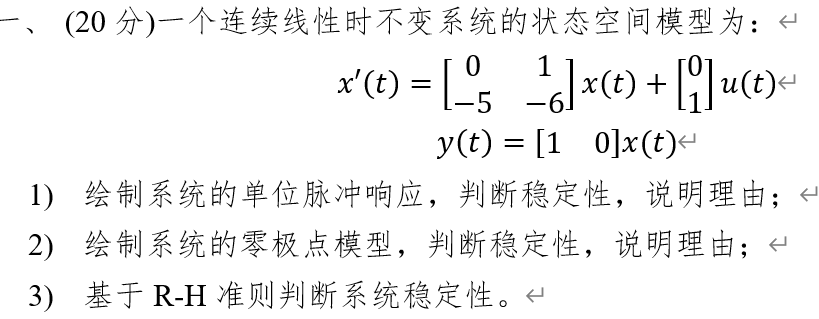

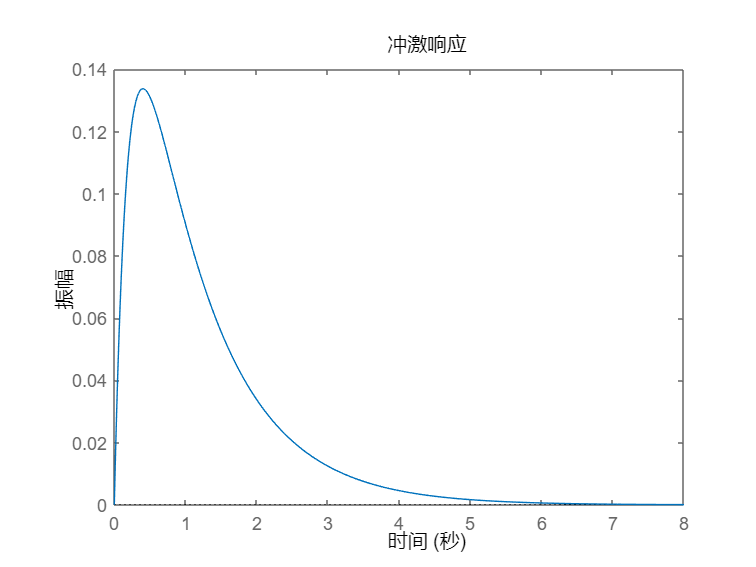

%%%%%%%%%(1)%%%%%%%%%%
t=0:0.01:8;
A=[0 1 ;-5 -6];
B=[0;1];
C=[1 0];
D=0;
sys0=ss(A,B,C,D);
figure(1);
impulse(sys0,t);

稳定性分析：最终单位脉冲响应趋于0，故而稳定。

%%%%%%%%%(2)%%%%%%%%%%
[z,p,k]=ss2zp(A,B,C,D)%求极零点


z =

  空的 0×1 double 列向量



p =     -1
    -5


k = 1

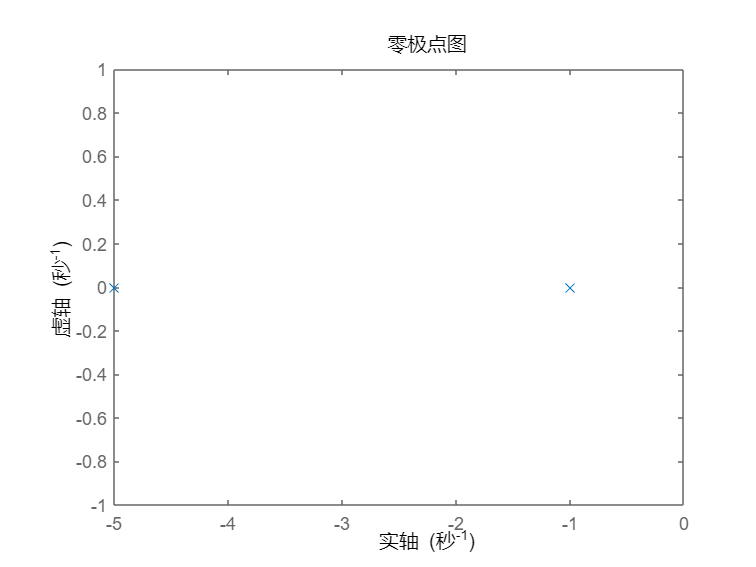

figure(2);
pzmap(sys0);

稳定性分析：极点全部位于左半平面，故而稳定。

%%%%%%%%%(3)%%%%%%%%%%
[a,b]=ss2tf(A,B,C,D)

a =      0     0     1


b =      1     6     5


q1=b;
n1=length(q1);
R1=zeros(3,3);
R1(1,1)=q1(1);R1(2,1)=q1(2);R1(1,2)=q1(3);
for i=3:n1
    for j=1:n1-1
        R1(i,j)=(R1(i-1,1)*R1(i-2,j+1)-R1(i-2,1)*R1(i-1,j+1))/R1(i-1,1);
    end
end
disp(R1);

     1     5     0
     6     0     0
     5     0     0



稳定性分析：罗斯-霍维斯数列的第一列全为正数，故系统稳定。

clear;
clc;

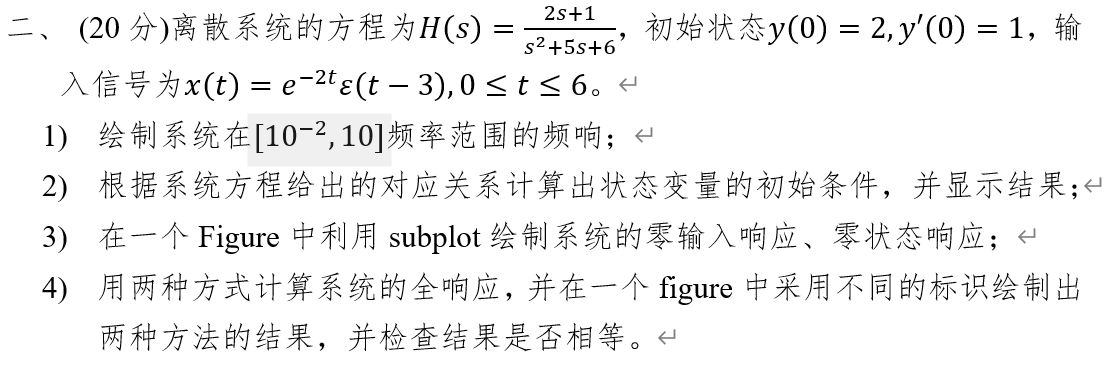

（是连续系统，不是离散系统）

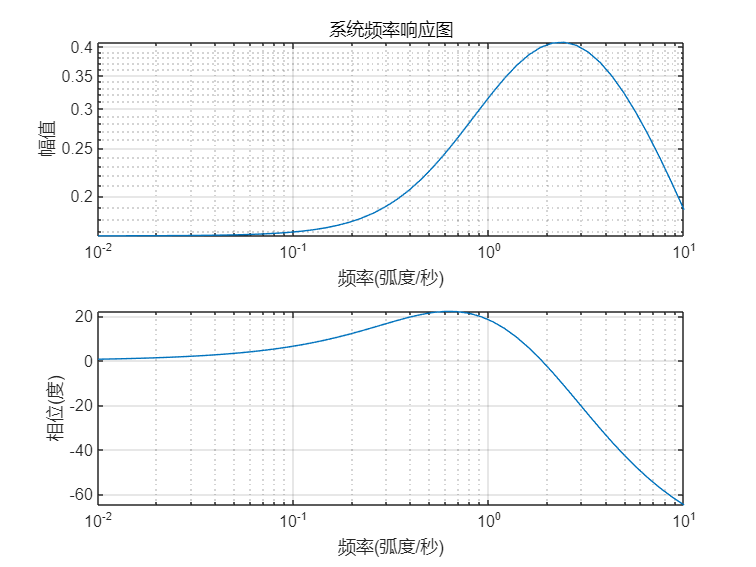

%%%%%%%%%(1)%%%%%%%%%%
num=[2 1];
den=[1 5 6];
w = logspace(-2, 1);% 创建对数刻度的频率向量
figure(3);
freqs(num, den, w);
title("系统频率响应图");

%%%%%%%%%(2)%%%%%%%%%%
[a, b, c, d] = tf2ss(num, den);% 将传递函数模型转换为状态空间模型 
sys0 = ss(a, b, c, d); 
R = inv([1,-a(1,1),-a(1,2);c(1),c(2),0;0,c(1),c(2)])*[0,1,2]';
disp(R);

   -0.3333
    1.6667
   -1.3333



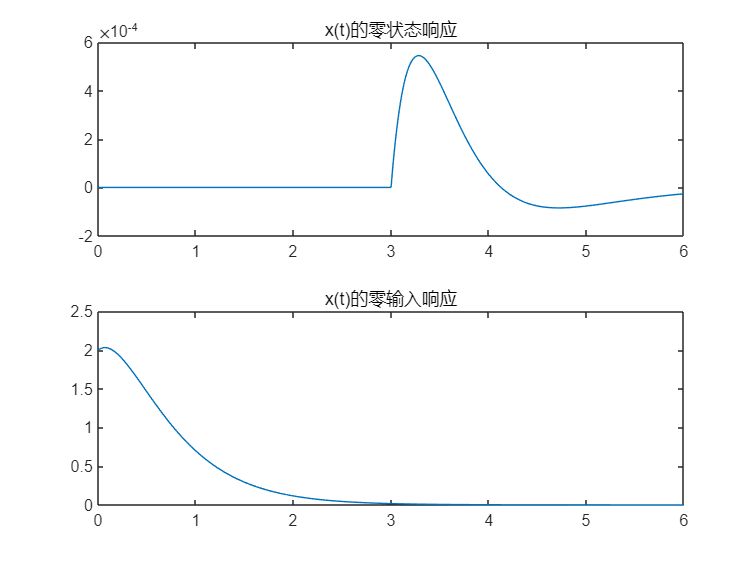

%%%%%%%%%(3)%%%%%%%%%%
t = 0:0.01:6;  % 定义时间向量
sys = tf(num, den);  
x = exp(-2*t).*stepfun(t,3); % 定义输入信号
% 计算并绘制零输入响应
y0 = initial(sys0, R(2:3), t);  % 使用initial函数计算零输入响应
% 计算并绘制零状态响应
y1 = lsim(sys, x, t);
figure(4); 
subplot(2,1,1);
plot(t, y1);  
title('x(t)的零状态响应');  
subplot(2,1,2);
plot(t, y0); 
title('x(t)的零输入响应'); 

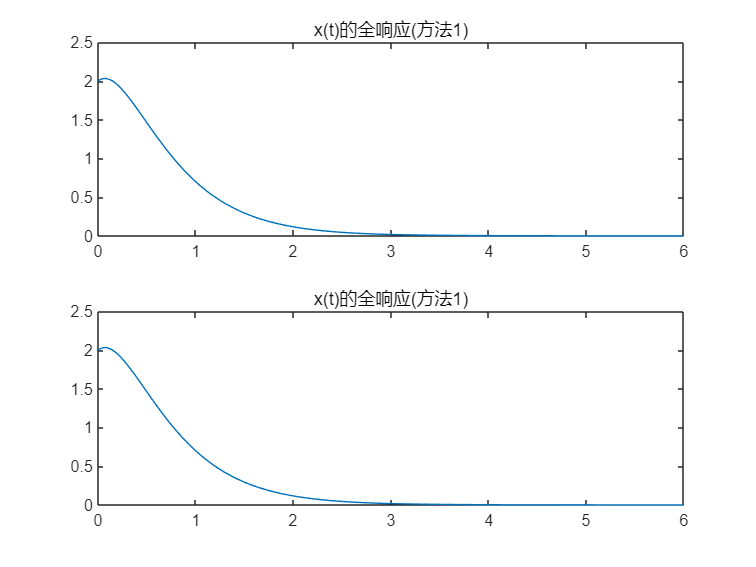

%%%%%%%%%(4)%%%%%%%%%%
% 方法1：全响应 = 零输入 + 零状态
yy = y0 + y1;  
% 方法2：直接求全响应
xx0=R(2:3);
yyy=lsim(sys0,x,t,xx0);%全响应
figure(5); 
subplot(2,1,1);
plot(t, yy); 
title('x(t)的全响应(方法1)');
subplot(2,1,2);
plot(t, yyy);
title('x(t)的全响应(方法1)');

clear;
clc;

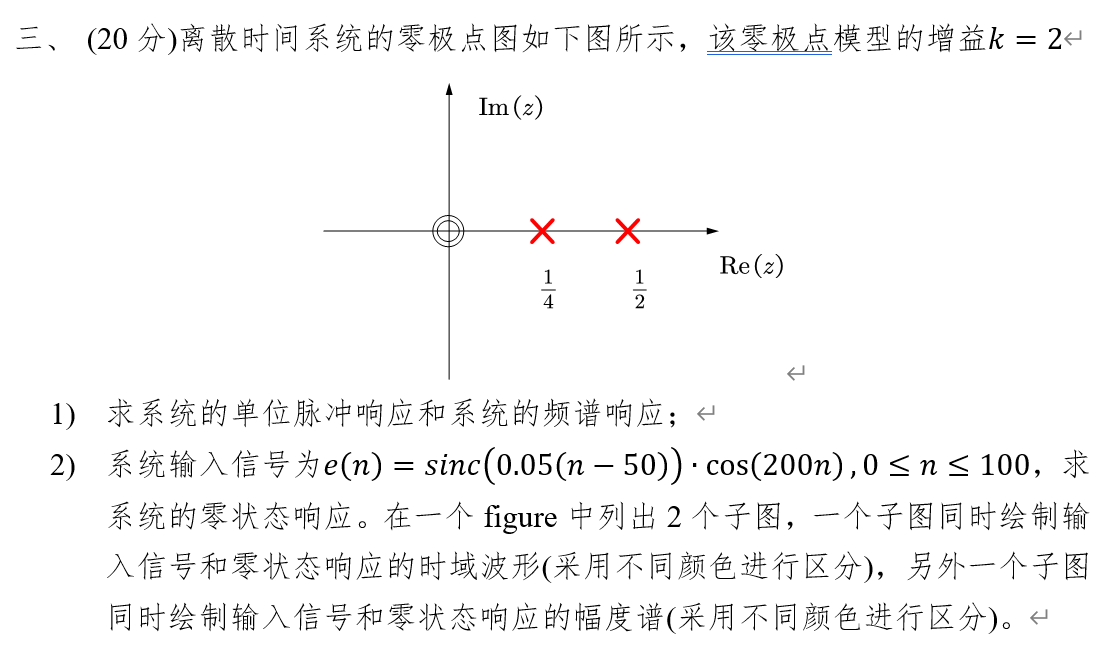

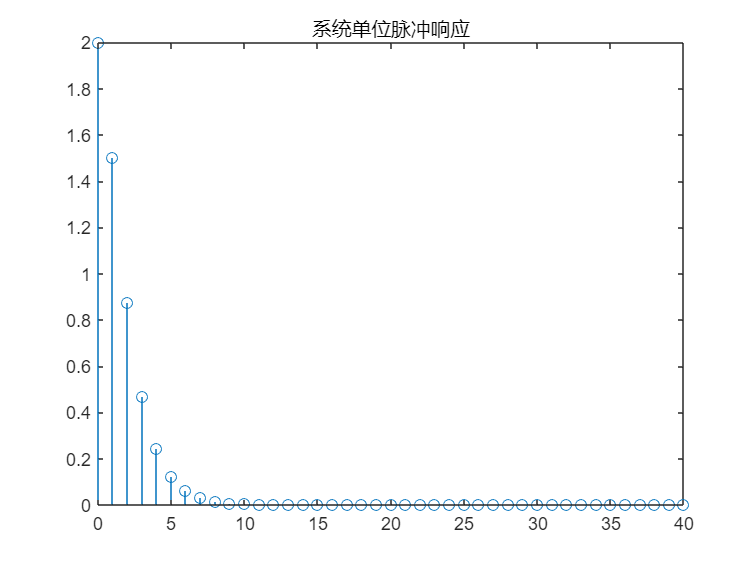

%%%%%%%%%(1)%%%%%%%%%%
n1=0:1:40;
k=2;
z=[0 ;0]; 
p=[1/4; 1/2];
[num,den]=zp2tf(z,p,k);
figure(7);
y1=dimpulse(num,den,41);
stem(n1,y1);
title('系统单位脉冲响应');

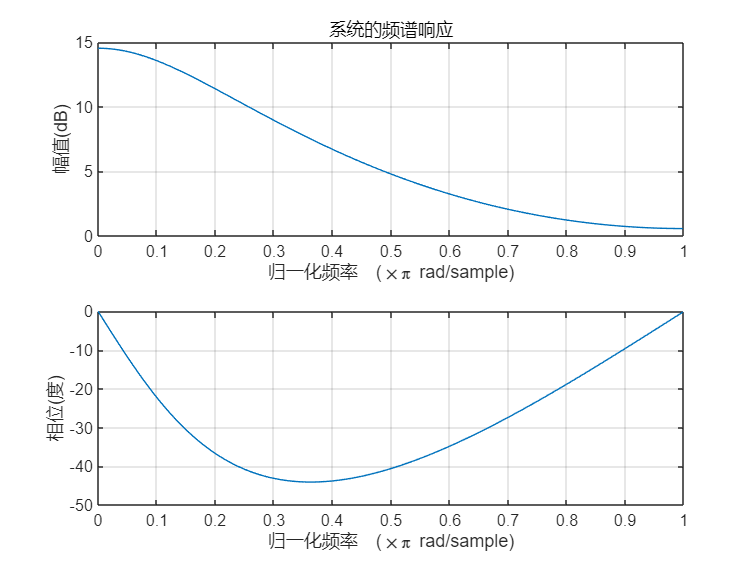

figure(8);
freqz(num, den);
title('系统的频谱响应');

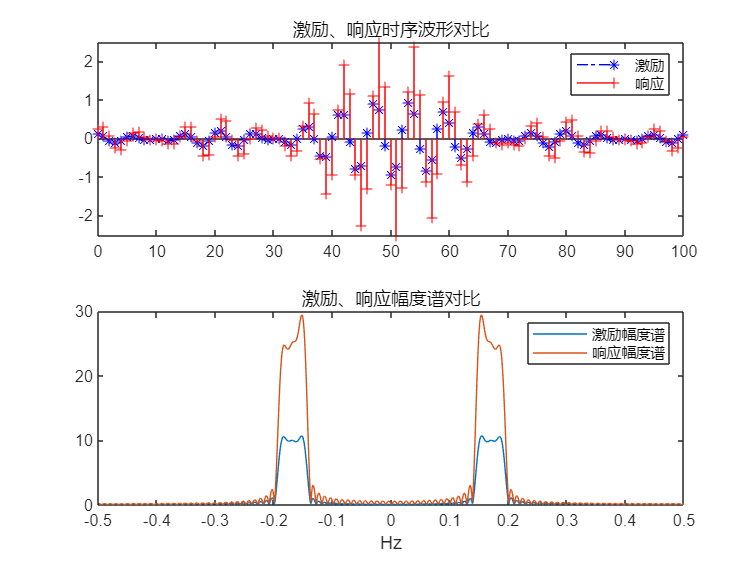

%%%%%%%%%(2)%%%%%%%%%%
n=0:1:100;
e=sinc(0.05*(n-50)+eps).*cos(200*n);
y2=filter(num,den,e);
N = 1024;
fs = 1;% 定义采样频率
w = -fs/2 + fs/N:fs/N:fs/2;
E = fftshift(fft(e, N));% 对时域信号进行快速傅里叶变换（FFT）
Y2=fftshift(fft(y2, N));

figure(9);
subplot(2,1,1);
stem(n,e,'*b-.');
hold on;
stem(n,y2,'-r+');
hold off;
legend("激励","响应");
title('激励、响应时序波形对比');

subplot(2,1,2);
plot(w,abs(E));
hold on;
plot(w,abs(Y2));
hold off;
xlabel("Hz");
legend("激励幅度谱","响应幅度谱");
title('激励、响应幅度谱对比');

clear;
clc;

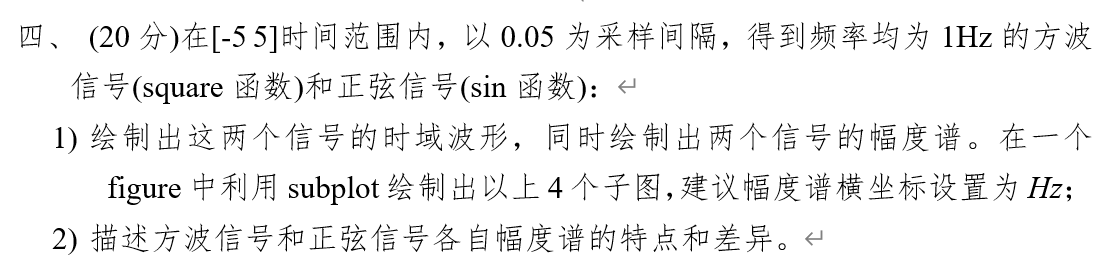

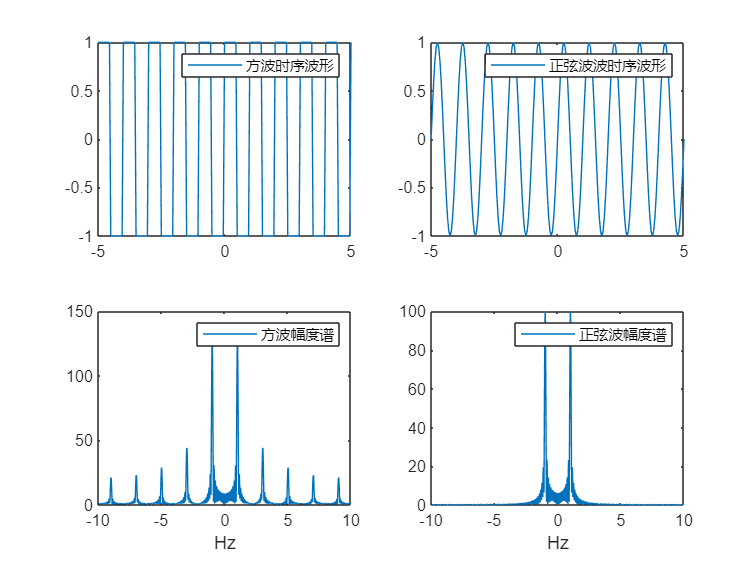

%%%%%%%%%(1)%%%%%%%%%%
fs = 20;% 定义采样频率
t=-5:1/fs:5;
N = 1024;
w = -fs/2 + fs/N:fs/N:fs/2;
figure();
subplot(2,2,1);
x1 = square(2*pi*1*t);
plot(t,x1);
legend("方波时序波形");

subplot(2,2,2);
x2 = sin(2*pi*1*t);
plot(t,x2);
legend("正弦波波时序波形");

subplot(2,2,3);
X1 = fftshift(fft(x1, N));% 对时域信号进行快速傅里叶变换（FFT）
plot(w,abs(X1));
xlabel("Hz");
legend("方波幅度谱");

subplot(2,2,4);
X2 = fftshift(fft(x2, N));
plot(w,abs(X2));
xlabel("Hz");
legend("正弦波幅度谱");

%%%%%%%%%(2)%%%%%%%%%%

特点：`正弦信号的幅度谱非常简单，只包含一个频率成分；`

`     方波信号的幅度谱则复杂得多，包含多个频率成分，并且随着频率的增加，幅度逐渐减小。`

差异：正弦波幅度谱的信号集中，而方波则较分散。

clear;
clc;

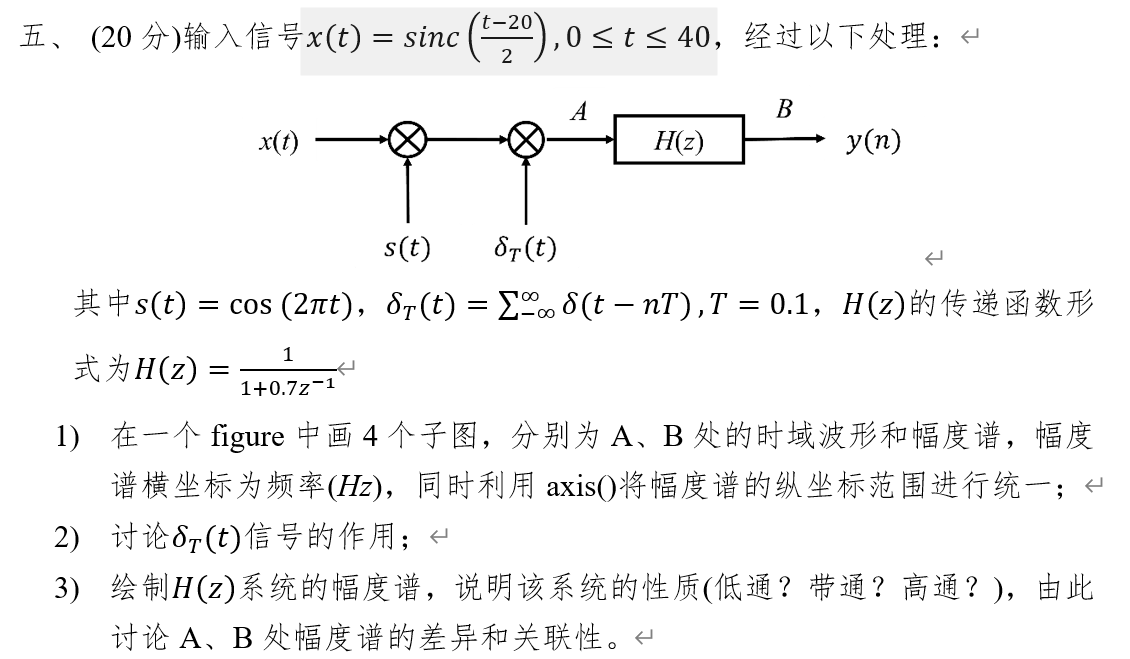

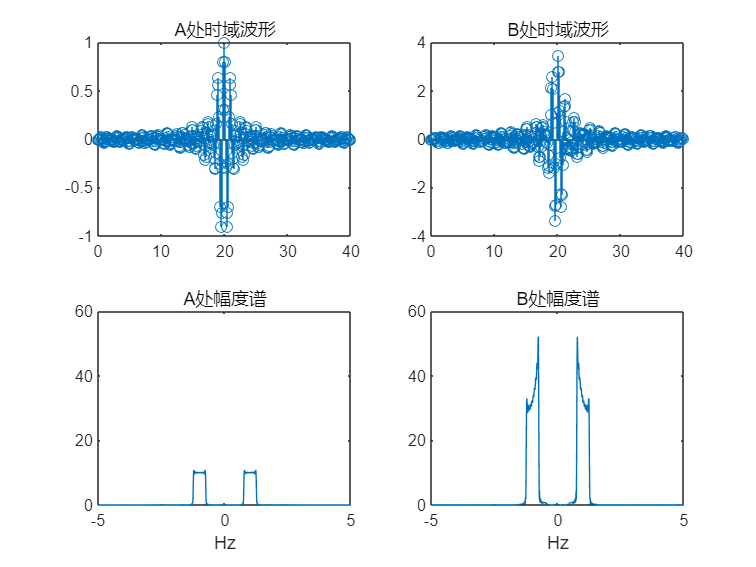

%%%%%%%%%%%%(1)%%%%%%%%%%%%%%
fs=10;
n=0:1/fs:40;
N = 1024;
w = -fs/2 + fs/N:fs/N:fs/2;
%%%%%输入信号%%%%%%
x=sinc((n-20)/2+eps);
s=cos(2*pi*n);
a=s.*x;
A=fftshift(fft(a,N));
%%%%%输出信号%%%%%%
num=[1 ];
den=[1 0.7];
h = impz(num, den, n);% 使用impz函数计算系统的脉冲响应
b = conv(a, h);% 使用conv函数计算输入信号与脉冲响应的卷积，得到输出信号
bb =b (1:401);%截取规定时间范围内的信号
B=fftshift(fft(bb,N));
%%%%%画图%%%%%%
figure();
subplot(2,2,1);stem(n,a);title('A处时域波形');
subplot(2,2,2);stem(n,bb);title('B处时域波形');
subplot(2,2,3);plot(w,abs(A));title('A处幅度谱');xlabel('Hz');ylim([0,60]);
subplot(2,2,4);plot(w,abs(B));title('B处幅度谱');xlabel('Hz');ylim([0,60]);

%%%%%%%%%%%%(2)%%%%%%%%%%%%%%

说明：该信号将连续的连续时间信号，以采样间隔T=0.1，采样为了离散时间信号，从而能通过之后的离散系统。

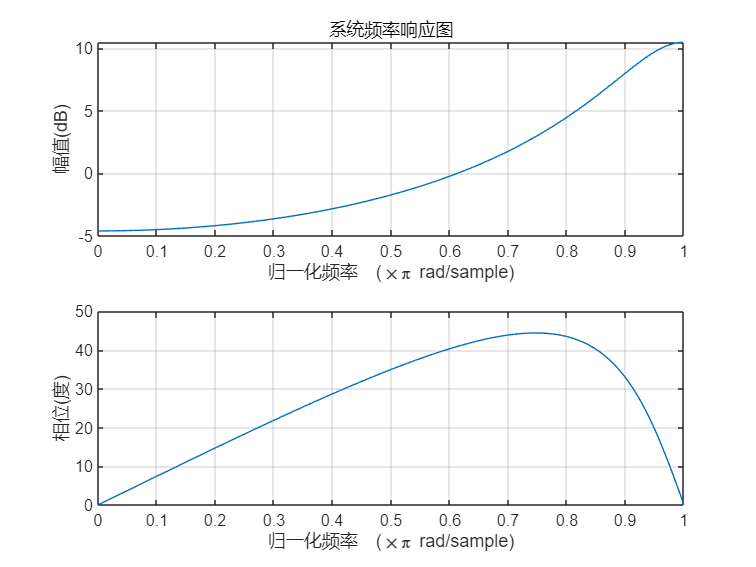

%%%%%%%%%%%%(3)%%%%%%%%%%%%%%
figure();
freqz(num, den);
title("系统频率响应图");

说明：该系统是高通系统。

差异：A的幅度谱峰值比B的要小，且A的幅度谱波峰是带状，而A的幅度谱波峰则是曲线型。

关联性：两者的幅度谱波峰中心频率接近。且都只有两个波峰